data = readtable('data/data1/CHID46.csv');
data = table2array(data);
data

data =    13.0000    4.0378
   16.0000    5.0338
   20.0000    5.9031
   23.0000    5.9649
   27.0000    5.5320
   30.0000    4.8910
   36.0000    4.4400
   38.0000    4.1673
   43.0000    4.2634



rng('default') % For reproducibility


bootstat = bootstrp(size(data,1),@mean,data);
bootstat

bootstat =    30.3333    4.7061
   32.4444    4.7539
   34.7778    4.3456
   22.4444    4.7237
   27.5556    4.9128
   28.6667    5.0114
   26.8889    5.2737
   28.7778    4.9489
   26.6667    5.2915


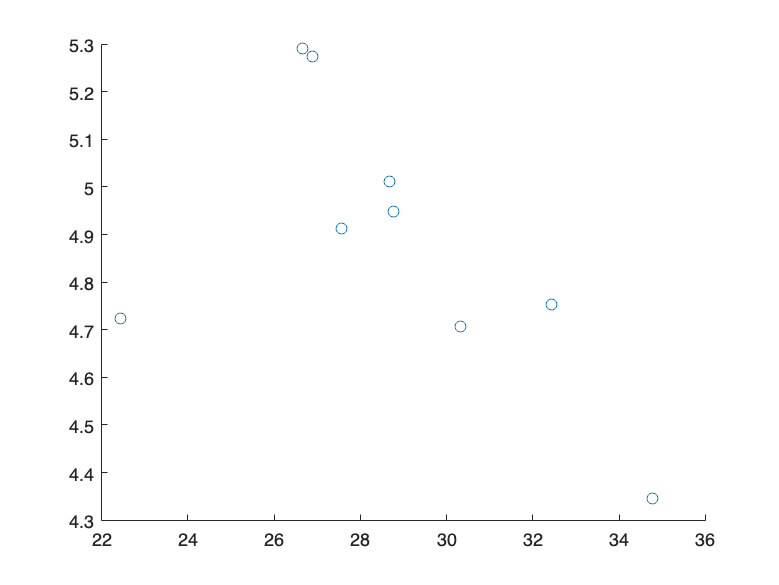

scatter(bootstat(:,1),bootstat(:,2))